# Adoption of programming languages

## Setup

Only when recomputing data extracted from apps, the following variables need to be set. Elaborating already extracted data available in the data2.mat file does not require this setup.

Run data-extracting code ONLY after running data-extracting code in selection.mlx, as it is needed to clone the app repositories.

Data-extracting code is commented not to disrupt the data-elaborating workflow.

In order for the data extracting code to work, it is necessary to setup the $PATH environment variable and Ruby environment version to execute terminal commands.

path = '$PATH';
rbenvVersion = "3.0.0";

Moreover, the location of the clones directory must be set:

clonesDir = '.';

## Programming languages adoption

In order to estimate the number of lines in each programming language for each app, I used the `cloc `command-line tool.

load ../../Data/data2.mat data

Column 11 of `data` contains a string array for each app signaling the name and location of the main `.xcodeproj` package, manually extracted. Apps that have multiple strings in the array have changed or moved the main `.xcodeproj` package over time.

The following code extracts, using the `cloc` tool, the number of lines of code for each language, for each commit of every app. In order for it to work, it is necessary to have `cloc `installed (using this guide: [https://github.com/AlDanial/cloc#install-via-package-manager](https://github.com/AlDanial/cloc#install-via-package-manager) ).

Before analyzing the commit, the code changes directory to the one containing the `.xcodeproj` package, by iterating over the array in column 11, to exclude files in the repository that do not belong to the app.

Moreover, the cloc terminal command is called with the `--exclude-dir` argument to exclude directories that usually contain dependency code.

The results are stored, for each commit, in the `languagePercentagesCloc `struct, having a struct field for each language, which contains a struct with, among others, the number of lines of code, excluding comments, in that language.

% indices_to_analyze = [1:size(data)];
% 
% for k = indices_to_analyze
% 
%     cd(clonesDir);
% 
%     for vc=1:size(data{k, 10})
%         pathToExplore = fullfile(clonesDir, data{k,8});
%         cd(pathToExplore)
%         system("git checkout --force " +  data{k, 10}(vc).tag, "PATH", path, "RBENV_VERSION", rbenvVersion);
%         
%         for j=1:length(data{k, 11})
%             if isfolder(data{k, 11}(j)) && isfile(fullfile(data{k, 11}(j), "/project.pbxproj"))
%                 pathToExplore = fullfile(pathToExplore, data{k, 11}(j), "..");
%                 break
%             end
%         end
% 
%         cd(pathToExplore)
% 
%         system("cloc . --json --exclude-dir=fastlane,Carthage,Vendor,vendor,Pods,.build > " + clonesDir + "/perc1.json", "PATH", path, "RBENV_VERSION", rbenvVersion);
%         cd(clonesDir)
%         str = fileread("perc1.json");
%         percentages = jsondecode(str);
%     
%         data{k, 10}(vc).languagePercentagesCloc = percentages;
%         "analyzed commit " + vc + " out of " + length(data{k, 10}) + " of app " + k
%     end
% end

To simplify the following elaboration process, this code computes the percentage of Objective-C and Swift code and stores them in a separate struct, stored as well in the column 10 of `data`, `ObjcSwiftCloc`, containing a struct for Swift and one for Objective-C containing, in their turn, a struct with the percentage and number of lines of code in that language.

% for vc = 1:size(data)
%     for j=1:size(data{vc, 10})
%         if isfield(data{vc, 10}(j).languagePercentagesCloc, "Swift")
%             swiftSize = data{vc, 10}(j).languagePercentagesCloc.Swift.code;
%         else
%             swiftSize = 0;
%         end
%         if isfield(data{vc, 10}(j).languagePercentagesCloc, "Objective_C")
%             objcSize = data{vc, 10}(j).languagePercentagesCloc.Objective_C.code;
%         else
%             objcSize = 0;
%         end
%         total = swiftSize + objcSize;
% 
%         swiftPercentage = swiftSize / total * 100;
%         objcPercentage = objcSize / total * 100;
% 
%         data{vc, 10}(j).ObjcSwiftCloc.Swift.percentage = swiftPercentage;
%         data{vc, 10}(j).ObjcSwiftCloc.Swift.size = swiftSize;
%         data{vc, 10}(j).ObjcSwiftCloc.Objective_C.percentage = objcPercentage;
%         data{vc, 10}(j).ObjcSwiftCloc.Objective_C.size = objcSize;
%     end
% end

The following code generates a plot with the cumulative usage of programming languages over time, accounting for the number of lines of code.

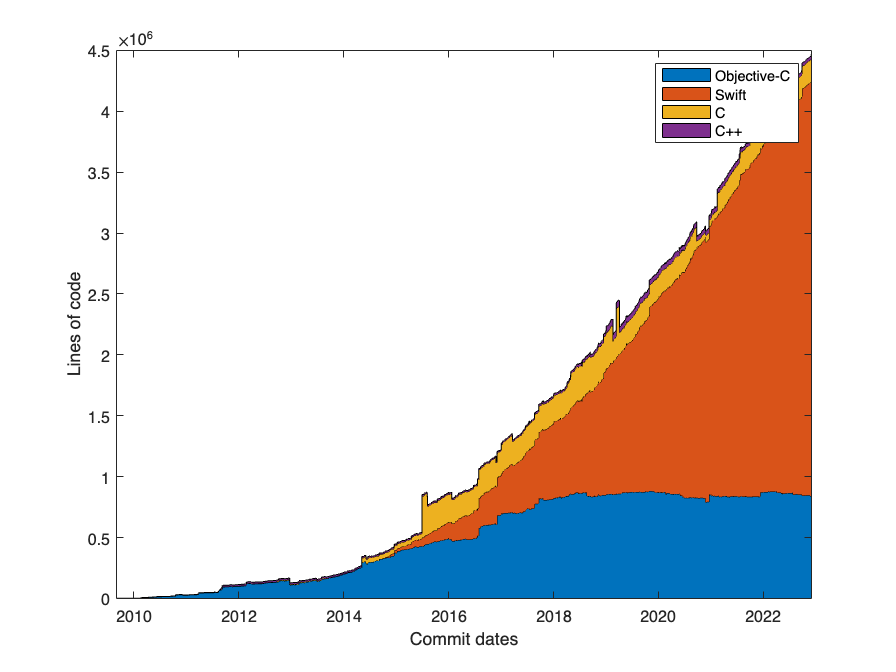

clear swiftFix1 objcFix1 CFix1 CppFix1 datesFix
swiftFix1 = [];
objcFix1 = [];
CFix1 = [];
CppFix1 = [];
datesFix = NaT;

for vc = setdiff(1:size(data), 9)
    dates = NaT;
    swift = [];
    objc = [];
    cpp = [];
    c = [];

    for j = 1:length(data{vc, 10})
        dates(j) = data{vc,10}(j).dateTime;
        if isfield(data{vc, 10}(j), "languagePercentagesCloc")
            if (isfield(data{vc,10}(j).languagePercentagesCloc, "Swift"))
                swift(j) = data{vc,10}(j).languagePercentagesCloc.Swift.code; 
            else
                swift(j) = 0;
            end
            
            if (isfield(data{vc,10}(j).languagePercentagesCloc, "C"))
                c(j) = data{vc,10}(j).languagePercentagesCloc.C.code;
            else
                c(j) = 0;
            end
            
            if (isfield(data{vc,10}(j).languagePercentagesCloc, "Objective_C"))
                objc(j) = data{vc,10}(j).languagePercentagesCloc.Objective_C.code;
            else
                objc(j) = 0;
            end

            if (isfield(data{vc,10}(j).languagePercentagesCloc, "C__"))
                cpp(j) = data{vc,10}(j).languagePercentagesCloc.C__.code;
            else
                cpp(j) = 0;
            end
        else
            swift(j) = 0;
            objc(j) = 0;
            cpp(j) = 0;
            c(j) = 0;
        end
    end

    swift = swift(1:end);
    objc = objc(1:end);
    cpp = cpp(1:end);
    c = c(1:end);

    an = swift;
    for i=2:length(swift)
        an(i) = swift(i) - swift(i-1);
    end

    bn = objc;
    for i=2:length(objc)
        bn(i) = objc(i) - objc(i-1);
    end

    cn = c;
    for i=2:length(c)
        cn(i) = c(i) - c(i-1);
    end

    dn = cpp;
    for i=2:length(cpp)
        dn(i) = cpp(i) - cpp(i-1);
    end

    swiftFix1 = [swiftFix1; an'];
    objcFix1 = [objcFix1; bn'];
    CFix1 = [CFix1; cn'];
    CppFix1 = [CppFix1; dn'];
    datesFix = [datesFix, dates(1:end)];
end

datesFix = datesFix';
datesFix = datesFix(2:end);

[datesFix, idx] = sort(datesFix, 'ascend');
swiftFix1 = swiftFix1(idx, :);
objcFix1 = objcFix1(idx, :);
CFix1 = CFix1(idx, :);
CppFix1 = CppFix1(idx, :);

swiftFix1 = cumsum(swiftFix1);
objcFix1 = cumsum(objcFix1);
CFix1 = cumsum(CFix1);
CppFix1 = cumsum(CppFix1);

figure;
area(datesFix, [objcFix1, swiftFix1, CFix1, CppFix1]);
xlim([datesFix(1) datesFix(end)])
hold off;
legend("Objective-C", "Swift", "C", "C++");
xlabel('Commit dates')
ylabel('Lines of code')

## The transition from Objective-C to Swift

To evaluate the transition from Objective-C to Swift, data collected before is sufficient. 

The following code plots the adoption of Swift vs Objective-C by analysing the percentage of code in each commit, dividing commits into four classes:

- onlySwift: more than 98% of the code is Swift code

- swift: between 50% and 98% of the code is Swift code

- objC: between 50% and 98% of the code is Objective-C code

- onlyObjC: more than 98% of the code is Objective-C code

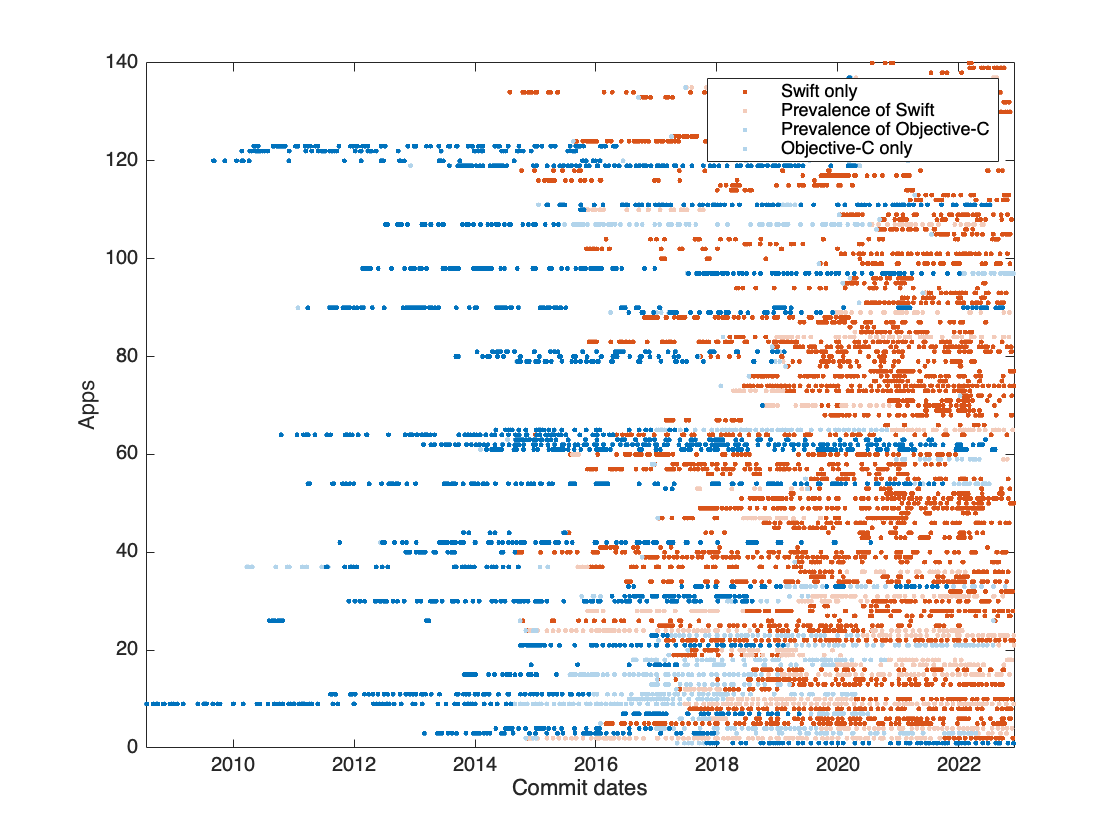

figure;
for vc = 1:length(data)
    s = 1;
    s1 = 1;
    o = 1;
    o1 = 1;
    onlySwiftDates = NaT;
    swiftDates = NaT;
    objCDates = NaT;
    onlyObjCDates = NaT;

    for j=1:length(data{vc,10})
        if data{vc,10}(j).ObjcSwiftCloc.Swift.percentage >= 98
            onlySwiftDates(s) = data{vc, 10}(j).dateTime;
            s = s + 1;
        elseif data{vc,10}(j).ObjcSwiftCloc.Swift.percentage > data{vc, 10}(j).ObjcSwiftCloc.Objective_C.percentage
            swiftDates(s1) = data{vc, 10}(j).dateTime;
            s1 = s1 + 1;
        elseif data{vc,10}(j).ObjcSwiftCloc.Objective_C.percentage >= 98
            onlyObjCDates(o) = data{vc, 10}(j).dateTime;
            o = o + 1;
        else
            objCDates(o1) = data{vc, 10}(j).dateTime;
            o1 = o1 + 1;
        end
    end

    plot(onlySwiftDates, repmat(vc, length(onlySwiftDates)), '.', 'Color', '#D95319');
    hold on;
    plot(swiftDates, repmat(vc, length(swiftDates)), '.', 'Color', "#F3CBBA");
    hold on;
    plot(objCDates, repmat(vc, length(objCDates)), '.', 'Color', "#B2D4EB");
    hold on;
    plot(onlyObjCDates, repmat(vc, length(onlyObjCDates)), '.', 'Color', "#0072BD");
    hold on;
end

legend("Swift only", "Prevalence of Swift", "Prevalence of Objective-C", "Objective-C only")
xlabel("Commit dates");
ylabel("Apps");
hold off;

The following code divides the app into classes based on their evolution in terms of adoption of programming languages, considering the first meaningful commit, and the latest. The computed arrays contain the list of app numbers belonging to the specific class. The arrays are named "from *language* to *language*", where *language* represents one of the four states cited earlier.

beginning = zeros(15, 4); %2008, 2022
latest = zeros(15, 4);
fromPureObjCToPureSwift = [];
fromPureObjCToMoreSwift = [];
fromMoreObjCToPureSwift = [];
fromPureObjCToMoreObjC  = [];
fromPureObjCToPureObjC  = [];
fromPureSwiftToPureSwift = [];
fromMoreObjCToMoreSwift = [];
fromMoreObjCToMoreObjC = [];
fromMoreSwiftToPureSwift = [];
fromMoreSwiftToMoreSwift = [];
fromPureSwiftToMoreSwift = [];

for vc = 1:size(data)
    initiallyPureObjC = false;
    initiallyMoreObjC = false;
    initiallyPureSwift = false;
    initiallyMoreSwift = false;
    toPureSwift = false;
    toMoreSwift = false;
    toMoreObjC = false;
    toPureObjC = false;

    firstIndex = 1;

    while isnan(data{vc,10}(firstIndex).ObjcSwiftCloc.Swift.percentage) && isnan(data{vc,10}(firstIndex).ObjcSwiftCloc.Objective_C.percentage)
        firstIndex = firstIndex + 1;
    end
    i = year(data{vc, 10}(firstIndex).dateTime) - 2007;

    if data{vc,10}(firstIndex).ObjcSwiftCloc.Swift.percentage >= 98
        beginning(i, 1) = beginning(i, 1) + 1;
        initiallyPureSwift = true;
    elseif data{vc,10}(firstIndex).ObjcSwiftCloc.Swift.percentage > data{vc, 10}(firstIndex).ObjcSwiftCloc.Objective_C.percentage
        beginning(i, 2) = beginning(i, 2) + 1;
        initiallyMoreSwift = true;
    elseif data{vc,10}(firstIndex).ObjcSwiftCloc.Objective_C.percentage >= 98
        beginning(i, 4) = beginning(i, 4) + 1;
        initiallyPureObjC = true;
    else
        beginning(i, 3) = beginning(i, 3) + 1;
        initiallyMoreObjC = true;
    end

    j = year(data{vc, 10}(end).dateTime) - 2007;

    if data{vc,10}(end).ObjcSwiftCloc.Swift.percentage >= 98
        latest(j, 1) = latest(j, 1) + 1;
        toPureSwift = true;
    elseif data{vc,10}(end).ObjcSwiftCloc.Swift.percentage > data{vc, 10}(end).ObjcSwiftCloc.Objective_C.percentage
        latest(j, 2) = latest(j, 2) + 1;
        toMoreSwift = true;
    elseif data{vc,10}(end).ObjcSwiftCloc.Objective_C.percentage >= 98
        latest(j, 4) = latest(j, 4) + 1;
        toPureObjC = true;
    else
        latest(j, 3) = latest(j, 3) + 1;
        toMoreObjC = true;
    end

    if initiallyPureObjC && toPureSwift
        fromPureObjCToPureSwift(end + 1) = vc;
    end
    if initiallyMoreObjC && toPureSwift
        fromMoreObjCToPureSwift(end + 1) = vc;
    end
    if initiallyPureObjC && toMoreSwift
        fromPureObjCToMoreSwift(end + 1) = vc;
    end
    if initiallyPureObjC && toMoreObjC
        fromPureObjCToMoreObjC(end + 1) = vc;
    end
    if initiallyPureObjC && toPureObjC
        fromPureObjCToPureObjC(end + 1) = vc;
    end
    if initiallyPureSwift && toPureSwift
        fromPureSwiftToPureSwift(end + 1) = vc;
    end
    if initiallyMoreObjC && toMoreSwift
        fromMoreObjCToMoreSwift(end + 1) = vc;
    end
    if initiallyMoreObjC && toMoreObjC
        fromMoreObjCToMoreObjC(end + 1) = vc;
    end
    if initiallyMoreSwift && toPureSwift
        fromMoreSwiftToPureSwift(end + 1) = vc;
    end
    if initiallyMoreSwift && toMoreSwift
        fromMoreSwiftToMoreSwift(end + 1) = vc;
    end
    if initiallyPureSwift && toMoreSwift
        fromPureSwiftToMoreSwift(end + 1) = vc;
    end
end

fromPureObjCToPureSwift

fromPureObjCToPureSwift =     26    30    37    40    44    53    64    70    79    80    81


fromPureObjCToMoreSwift

fromPureObjCToMoreSwift =      3     4     9    15    17    21    23    31    65    89   107   110   137


fromMoreObjCToPureSwift

fromMoreObjCToPureSwift =      6    10


fromPureObjCToMoreObjC

fromPureObjCToMoreObjC =      7    11    33    54    97   111   119   120


fromPureObjCToPureObjC

fromPureObjCToPureObjC =      1    42    61    62    63    90    98   122   123


fromPureSwiftToPureSwift

fromPureSwiftToPureSwift =      2     5     8    12    13    14    16    22    25    27    29    32    34    35    36    38    39    41    43    45    46    47    48    49    50    51    52    55    56    57    58    60    66    67    68    69    71    72    74    75    76    77    78    82    83    86    87    88    91    92


fromMoreObjCToMoreSwift

fromMoreObjCToMoreSwift =     18    59


fromMoreObjCToMoreObjC


fromMoreObjCToMoreObjC =

     []



fromMoreSwiftToPureSwift

fromMoreSwiftToPureSwift =     28    73    85    93


fromMoreSwiftToMoreSwift

fromMoreSwiftToMoreSwift = 135

fromPureSwiftToMoreSwift

fromPureSwiftToMoreSwift =     19    20    24    84


The following code shows the distribution of the evolution of the usage of programming languages, for apps always written in Swift, apps always written in Objective-C, and apps which adopted both languages.

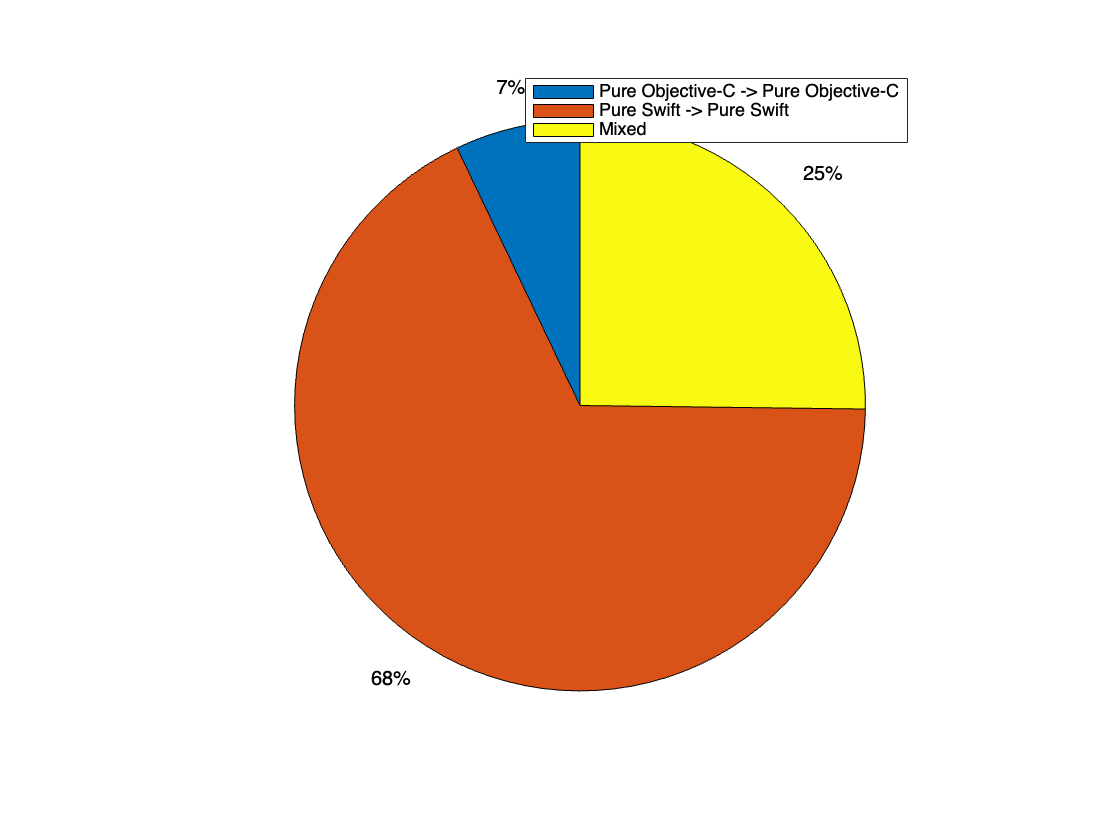

figure;
p = pie([length(fromPureObjCToPureObjC), length(fromPureSwiftToPureSwift), length(fromPureObjCToPureSwift) + length(fromMoreObjCToPureSwift) + length(fromPureObjCToMoreObjC) + length(fromMoreObjCToMoreSwift) + length(fromMoreObjCToMoreObjC) + length(fromMoreSwiftToPureSwift) + length(fromMoreSwiftToMoreSwift) + length(fromPureSwiftToMoreSwift)]);
legend("Pure Objective-C -> Pure Objective-C", "Pure Swift -> Pure Swift", "Mixed")
p(3).FaceColor = "#D95319";
p(1).FaceColor = "#0072BD";

The following code shows the distribution of the evolution of the usage of programming languages, for apps which adopted both languages, highlighting their how their behaviour changed.

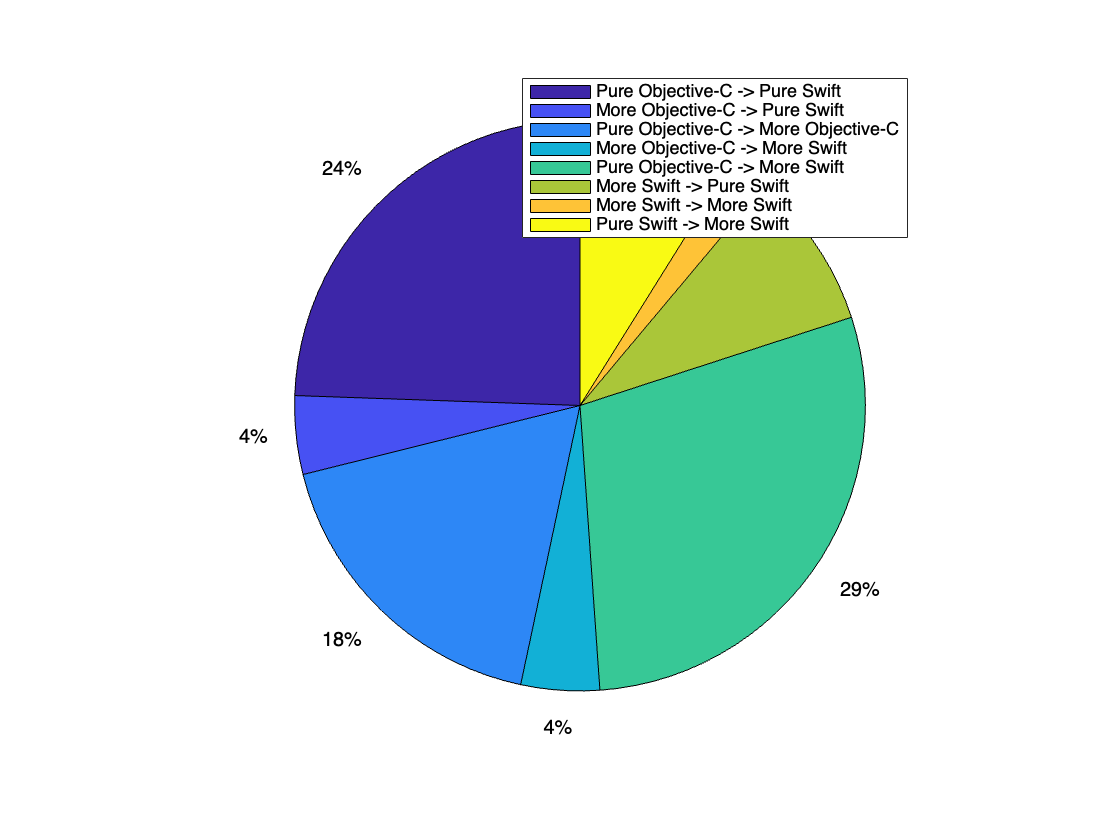

figure;
pie([length(fromPureObjCToPureSwift), length(fromMoreObjCToPureSwift), length(fromPureObjCToMoreObjC), length(fromMoreObjCToMoreSwift), length(fromPureObjCToMoreSwift), length(fromMoreSwiftToPureSwift), length(fromMoreSwiftToMoreSwift), length(fromPureSwiftToMoreSwift)])
legend("Pure Objective-C -> Pure Swift", "More Objective-C -> Pure Swift", "Pure Objective-C -> More Objective-C", "More Objective-C -> More Swift", "Pure Objective-C -> More Swift", "More Swift -> Pure Swift", "More Swift -> More Swift", "Pure Swift -> More Swift")

The following code plots the distribution of the usage of programming languages in the first meaningful commit of each app.

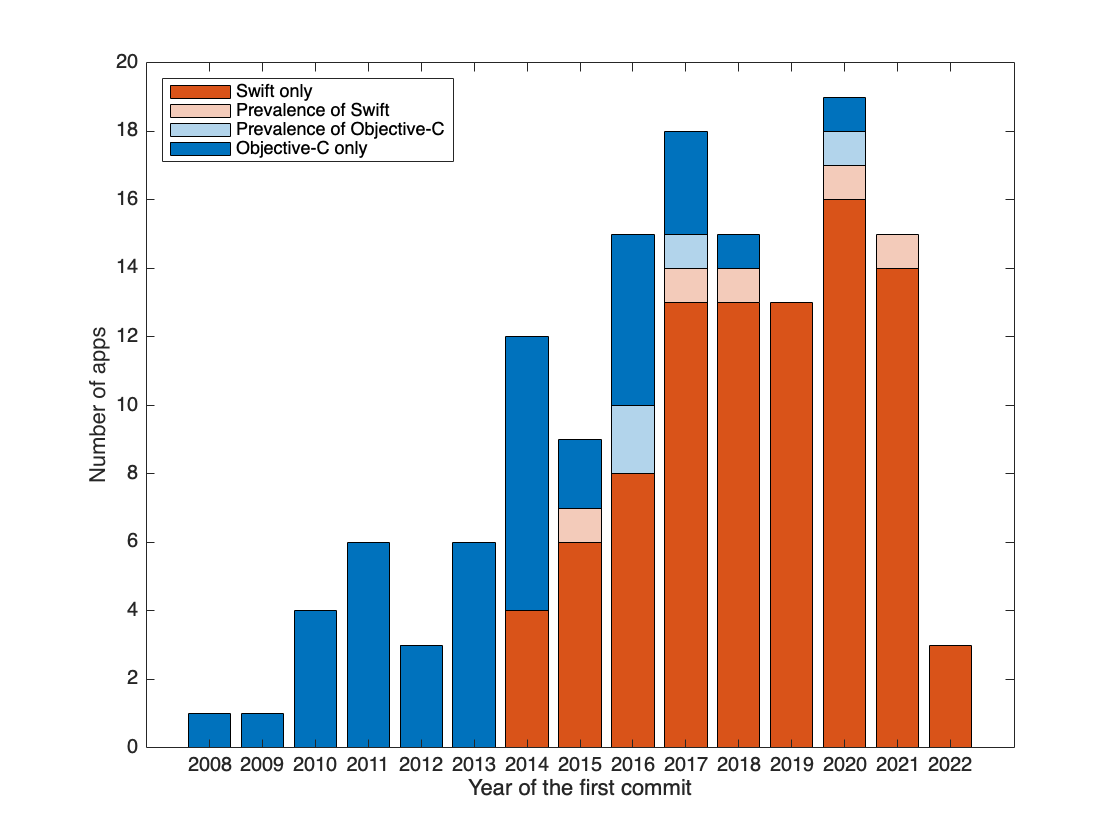

figure;
b = bar([2008:2022], beginning, 'stacked');
b(1).FaceColor = "#D95319";
b(2).FaceColor = "#F3CBBA";
b(3).FaceColor = "#B2D4EB";
b(4).FaceColor = "#0072BD";
legend("Swift only", "Prevalence of Swift", "Prevalence of Objective-C", "Objective-C only", 'Location', 'northwest')
xlabel("Year of the first commit");
ylabel("Number of apps");

The following code plots the distribution of the usage of programming languages in the latest commit of each app.

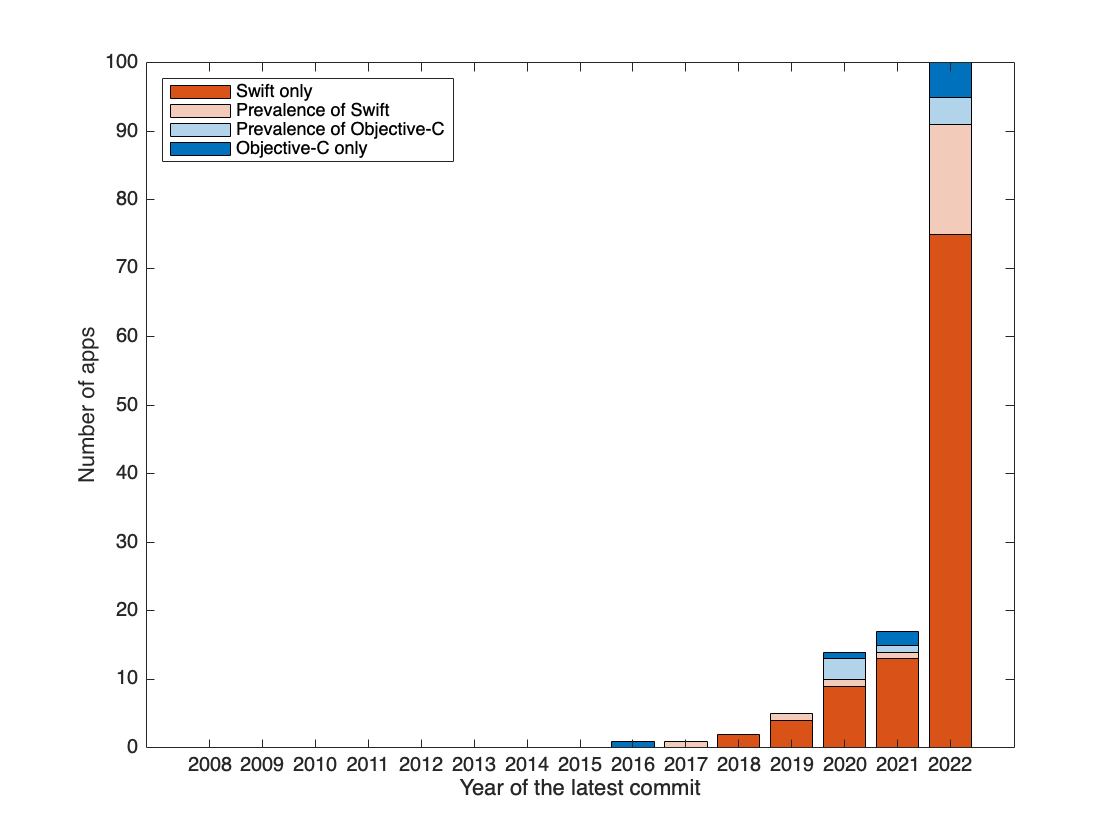

figure;
b = bar([2008:2022], latest, 'stacked');
b(1).FaceColor = "#D95319";
b(2).FaceColor = "#F3CBBA";
b(3).FaceColor = "#B2D4EB";
b(4).FaceColor = "#0072BD";
legend("Swift only", "Prevalence of Swift", "Prevalence of Objective-C", "Objective-C only", 'Location', 'northwest')
xlabel("Year of the latest commit");
ylabel("Number of apps");

The following code, given an app number or an array of app numbers, such as one of the formerly generated classes, shows its language adoption history with a histogram.

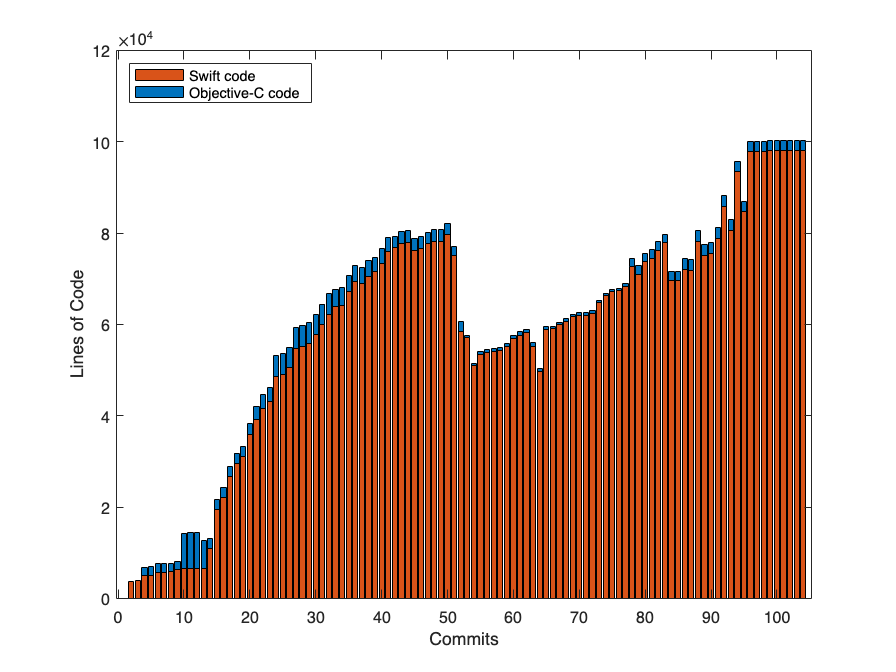

for i=24
    dates = NaT;
    swift = [];
    objC = [];
    for j=1:length(data{i, 10})
        dates(j) = data{i, 10}(j).dateTime;
        swift(j) = data{i, 10}(j).ObjcSwiftCloc.Swift.size;
        objC(j) = data{i, 10}(j).ObjcSwiftCloc.Objective_C.size;
    end

    figure('Name', i + " " + data{i, 8});
    b = bar(1:length(dates), [swift; objC], 'stacked');
    b(1).FaceColor = "#D95319";
    b(2).FaceColor = "#0072BD";
    legend("Swift code", "Objective-C code", 'Location', 'northwest')
    xlabel("Commits");
    ylabel("Lines of Code");
end

## Adoption of Swift versions

Gathering data about Swift versions adopted in each commit implies the analysis of the project metadata contained in the `project.pbxproj `file inside the `.xcodeproj` package of each app. Again, before analyzing the commit, the code changes directory to the one containing the `.xcodeproj` package, by iterating over the array in column 11. 

Commits that do not have a `.xcodeproj` package and rely on the `yonaskolb/XcodeGen` command-line tool have their `.xcodeproj` package generated by invoking the terminal command contained in column 12 of `data`. Data in column 12 was obtained manually. The use of `XcodeGen` requires to be installed using the instructions at [https://github.com/yonaskolb/XcodeGen#installing](https://github.com/yonaskolb/XcodeGen#installing) .

The following code extracts Swift versions, supported iOS versions and supported device types, when available, from the `project.pbxproj` file after converting it to JSON using Apple `plutil` command-line tool already available in macOS.

Extracted data is stored in the struct at column 10 of each app, respectively in the `iOSVersion`, `swiftVersion`, `targetedDeviceFamily` fields of each commit.

% for k= 1:size(data)
%     cd(clonesDir)
%     for vc=1:size(data{k, 10})
%         cd(clonesDir)
%         cd(data{k, 8});
%         system("git checkout --force " +  data{k, 10}(vc).tag, "PATH", path, "RBENV_VERSION", rbenvVersion);
%         
%         for j=1:length(data{k, 11})
%             if not(isempty(data{k, 12}))
%                 system(data{k, 12}, "PATH", path, "RBENV_VERSION", rbenvVersion);
%             end
%             if data{k, 11}(j) ~= "NO"
%                 cd(clonesDir)
%                 cd(data{k, 8});
%                 
%                 if isfolder(data{k, 11}(j)) && isfile(fullfile(data{k, 11}(j), "/project.pbxproj"))
%                     cd(data{k, 11}(j))
%                     system("plutil -convert json project.pbxproj -o " + clonesDir + "/convertedpbxproj.json", "PATH", path, "RBENV_VERSION", rbenvVersion);
% 
%                     cd(clonesDir)
%                     str = fileread("convertedpbxproj.json");
%                     project = jsondecode(str);
% 
%                     rootObject = matlab.lang.makeValidName(convertCharsToStrings(project.rootObject));
%                     targets = matlab.lang.makeValidName(convertCharsToStrings(project.objects.(rootObject(1)).targets));
%                     
%                     % filter targets whose product type is "com.apple.product-type.application"
%                     iOSSet = false;
%                     swiftSet = false;
%                     targetedSet = false;
% 
%                     for t=1:length(targets)
%                         if isfield(project.objects, targets(t)) && isfield(project.objects.(targets(t)), "productType") && project.objects.(targets(t)).productType == "com.apple.product-type.application"
%                             buildConfigList = matlab.lang.makeValidName(convertCharsToStrings(project.objects.(targets(t)).buildConfigurationList));
%                             buildConfigs = matlab.lang.makeValidName(convertCharsToStrings(project.objects.(buildConfigList).buildConfigurations));
%                         
%                             try
%                                 data{k, 10}(vc).iOSVersion = project.objects.(buildConfigs(1)).buildSettings.IPHONEOS_DEPLOYMENT_TARGET;
%                                 iOSSet = true;
%                             catch
%                             end
%                             
%                             try
%                                 data{k, 10}(vc).swiftVersion = project.objects.(buildConfigs(1)).buildSettings.SWIFT_VERSION;
%                                 swiftSet = true;
%                             catch
%                             end
%                     
%                             try
%                                 data{k, 10}(vc).targetedDeviceFamily = project.objects.(buildConfigs(1)).buildSettings.TARGETED_DEVICE_FAMILY;
%                                 targetedSet = true;
%                             catch
%                             end
%                         end
%                     end
% 
%                     if ~iOSSet || ~swiftSet || ~targetedSet
%                         buildConfigList = matlab.lang.makeValidName(convertCharsToStrings(project.objects.(rootObject(1)).buildConfigurationList));
%                         buildConfigs = matlab.lang.makeValidName(convertCharsToStrings(project.objects.(buildConfigList).buildConfigurations));
% 
%                         if ~iOSSet
%                             try
%                                 data{k, 10}(vc).iOSVersion = project.objects.(buildConfigs(1)).buildSettings.IPHONEOS_DEPLOYMENT_TARGET;
%                                 iOSSet = true;
%                             catch
%                             end
%                         end
% 
%                         if ~swiftSet
%                             try
%                                 data{k, 10}(vc).swiftVersion = project.objects.(buildConfigs(1)).buildSettings.SWIFT_VERSION;
%                                 swiftSet = true;
%                             catch
%                             end
%                         end
% 
%                         if ~targetedSet
%                             try
%                                 data{k, 10}(vc).targetedDeviceFamily = project.objects.(buildConfigs(1)).buildSettings.TARGETED_DEVICE_FAMILY;
%                                 targetedSet = true;
%                             catch
%                             end
%                         end
%                     end
% 
%                     if ~iOSSet || ~swiftSet || ~targetedSet
%                         for t=1:length(targets)
%                             if isfield(project.objects, targets(t)) && isfield(project.objects.(targets(t)), "productType") && project.objects.(targets(t)).productType ~= "com.apple.product-type.application"
%                                 buildConfigList = matlab.lang.makeValidName(convertCharsToStrings(project.objects.(targets(t)).buildConfigurationList));
%                                 buildConfigs = matlab.lang.makeValidName(convertCharsToStrings(project.objects.(buildConfigList).buildConfigurations));
%                             
%                                 if ~iOSSet
%                                     try
%                                         data{k, 10}(vc).iOSVersion = project.objects.(buildConfigs(1)).buildSettings.IPHONEOS_DEPLOYMENT_TARGET;
%                                         iOSSet = true;
%                                     catch
%                                     end
%                                 end
%                                 
%                                 if ~swiftSet
%                                     try
%                                         data{k, 10}(vc).swiftVersion = project.objects.(buildConfigs(1)).buildSettings.SWIFT_VERSION;
%                                         swiftSet = true;
%                                     catch
%                                     end
%                                 end
%                         
%                                 if ~targetedSet
%                                     try
%                                         data{k, 10}(vc).targetedDeviceFamily = project.objects.(buildConfigs(1)).buildSettings.TARGETED_DEVICE_FAMILY;
%                                         targetedSet = true;
%                                     catch
%                                     end
%                                 end
%                             end
%                         end
%                     end
% 
%                     "analyzed commit "+ vc + " out of " + length(data{k, 10}) + " of app " + k
%                     break
%                 elseif j == length(data{k, 11})
%                         "ignoring commit " + vc + " of app " + k
%                         data{k, 10}(vc).targetedDeviceFamily = [];
%                         data{k, 10}(vc).swiftVersion = [];
%                         data{k, 10}(vc).iOSVersion = [];
%                 end
%             end
%         end
%     end
% end

The following code shows a general plot of the evolution in the adoption of different versions of Swift, highliting the version adopted in each commit.

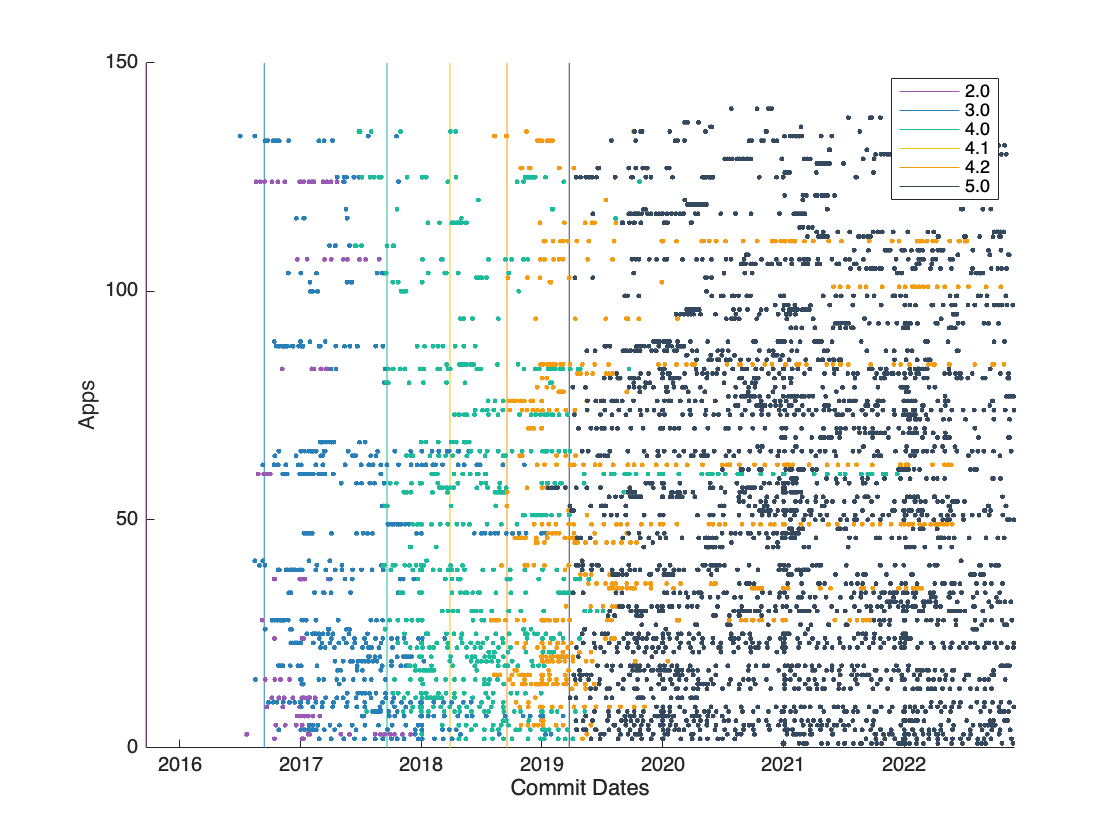

d1 = NaT;
d2 = NaT;
d3 = NaT;
d4 = NaT;
d41 = NaT;
d42 = NaT;
d5 = NaT;
d51 = NaT;
d52 = NaT;
d53 = NaT;
d54 = NaT;
d55 = NaT;
d56 = NaT;
d57 = NaT;

figure;
line([datetime("2015-09-21",'InputFormat','yyyy-MM-dd'), datetime("2015-09-21",'InputFormat','yyyy-MM-dd')], [0, 150], 'LineStyle', "-", 'Color', '#9B59B6');
hold on;
line([datetime("2016-09-13",'InputFormat','yyyy-MM-dd'), datetime("2016-09-13",'InputFormat','yyyy-MM-dd')], [0, 150], 'LineStyle', "-", 'Color', '#2980B9');
hold on;
line([datetime("2017-09-19",'InputFormat','yyyy-MM-dd'), datetime("2017-09-19",'InputFormat','yyyy-MM-dd')], [0, 150], 'LineStyle', "-", 'Color', '#1ABC9C');
hold on;
line([datetime("2018-03-29",'InputFormat','yyyy-MM-dd'), datetime("2018-03-29",'InputFormat','yyyy-MM-dd')], [0, 150], 'LineStyle', "-", 'Color', '#F1C40F');
hold on;
line([datetime("2018-09-17",'InputFormat','yyyy-MM-dd'), datetime("2018-09-17",'InputFormat','yyyy-MM-dd')], [0, 150], 'LineStyle', "-", 'Color', '#F39C12');
hold on;
line([datetime("2019-03-25",'InputFormat','yyyy-MM-dd'), datetime("2019-03-25",'InputFormat','yyyy-MM-dd')], [0, 150], 'LineStyle', "-", 'Color', '#34495E');
hold on;


indices = [1:length(data)];
for vc = indices
    
    i1 = 1;
    i2 = 1;
    i3 = 1;
    i4 = 1;
    i41 = 1;
    i42 = 1;
    i5 = 1;
    i51 = 1;
    i52 = 1;
    i53 = 1;
    i54 = 1;
    i55 = 1;
    i56 = 1;
    i57 = 1;
    ver1 = NaT;
    ver2 = NaT;
    ver3 = NaT;
    ver4 = NaT;
    ver41 = NaT;
    ver42 = NaT;
    ver5 = NaT;
    ver51 = NaT;
    ver52 = NaT;
    ver53 = NaT;
    ver54 = NaT;
    ver55 = NaT;
    ver56 = NaT;
    ver57 = NaT;
    f1 = true;
    f2 = true;
    f3 = true;
    f4 = true;
    f41 = true;
    f42 = true;
    f5 = true;
    f51 = true;
    f52 = true;
    f53 = true;
    f54 = true;
    f55 = true;
    f56 = true;
    f57 = true;

    for j=1:length(data{vc,10})
        if isfield(data{vc,10}(j), "swiftVersion") && not(isempty(data{vc,10}(j).swiftVersion))
            version = str2double(data{vc,10}(j).swiftVersion);

            if version >= 5.7
                if f57
                    d57(end+1) = data{vc, 10}(j).dateTime;
                    f57 = false;
                end
                ver57(i57) = data{vc, 10}(j).dateTime;
                i57 = i57 + 1;
            elseif version >= 5.6
                if f56
                    d56(end+1) = data{vc, 10}(j).dateTime;
                    f56 = false;
                end
                ver56(i56) = data{vc, 10}(j).dateTime;
                i56 = i56 + 1;
            elseif version >= 5.5
                if f55
                    d55(end+1) = data{vc, 10}(j).dateTime;
                    f55 = false;
                end
                ver55(i55) = data{vc, 10}(j).dateTime;
                i55 = i55 + 1;
            elseif version >= 5.4
                if f54
                    d54(end+1) = data{vc, 10}(j).dateTime;
                    f54 = false;
                end
                ver54(i54) = data{vc, 10}(j).dateTime;
                i54 = i54 + 1;
            elseif version >= 5.3
                if f53
                    d53(end+1) = data{vc, 10}(j).dateTime;
                    f53 = false;
                end
                ver53(i53) = data{vc, 10}(j).dateTime;
                i53 = i53 + 1;
            elseif version >= 5.2
                if f52
                    d52(end+1) = data{vc, 10}(j).dateTime;
                    f52 = false;
                end
                ver52(i52) = data{vc, 10}(j).dateTime;
                i52 = i52 + 1;
            elseif version >= 5.1
                if f51
                    d51(end+1) = data{vc, 10}(j).dateTime;
                    f51 = false;
                end
                ver5(i51) = data{vc, 10}(j).dateTime;
                i51 = i51 + 1;
            elseif version >= 5
                if f5
                    d5(end+1) = data{vc, 10}(j).dateTime;
                    f5 = false;
                end
                ver5(i5) = data{vc, 10}(j).dateTime;
                i5 = i5 + 1;
            elseif version >= 4.2
                if f42
                    d42(end+1) = data{vc, 10}(j).dateTime;
                    f42 = false;
                end
                ver42(i42) = data{vc, 10}(j).dateTime;
                i42 = i42 + 1;
            elseif version >= 4.1
                if f41
                    d41(end+1) = data{vc, 10}(j).dateTime;
                    f41 = false;
                end
                ver41(i41) = data{vc, 10}(j).dateTime;
                i4 = i4 + 1;
            elseif version >= 4
                if f4
                    d4(end+1) = data{vc, 10}(j).dateTime;
                    f4 = false;
                end
                ver4(i4) = data{vc, 10}(j).dateTime;
                i4 = i4 + 1;
            elseif version >= 3
                if f3
                    d3(end+1) = data{vc, 10}(j).dateTime;
                    f3 = false;
                end
                ver3(i3) = data{vc, 10}(j).dateTime;
                i3 = i3 + 1;
            elseif version >= 2
                if f2
                    d2(end+1) = data{vc, 10}(j).dateTime;
                    f2 = false;
                end
                ver2(i2) = data{vc, 10}(j).dateTime;
                i2 = i2 + 1;
            end
        elseif (data{vc,10}(j).ObjcSwiftCloc.Swift.size > 0)
            ver1(i1) = data{vc, 10}(j).dateTime;
            i1 = i1 + 1;
        end
    end

    plot(ver2, repmat(vc, length(ver2)), '.', 'Color', "#9B59B6");
    hold on;
    plot(ver3, repmat(vc, length(ver3)), '.', 'Color', "#2980B9");
    hold on;
    plot(ver4, repmat(vc, length(ver4)), '.', 'Color', "#1ABC9C");
    hold on;
    plot(ver41, repmat(vc, length(ver41)), '.', 'Color', "#F1C40F");
    hold on;
    plot(ver42, repmat(vc, length(ver42)), '.', 'Color', "#F39C12");
    hold on;
    plot(ver5, repmat(vc, length(ver5)), '.', 'Color', "#34495E");
    hold on;
end

legend("2.0", "3.0", "4.0", "4.1", "4.2", "5.0");
xlabel("Commit Dates")
ylabel("Apps")
hold off;

The following code shows how the evolution in the adoption of successive versions of Swift took place.

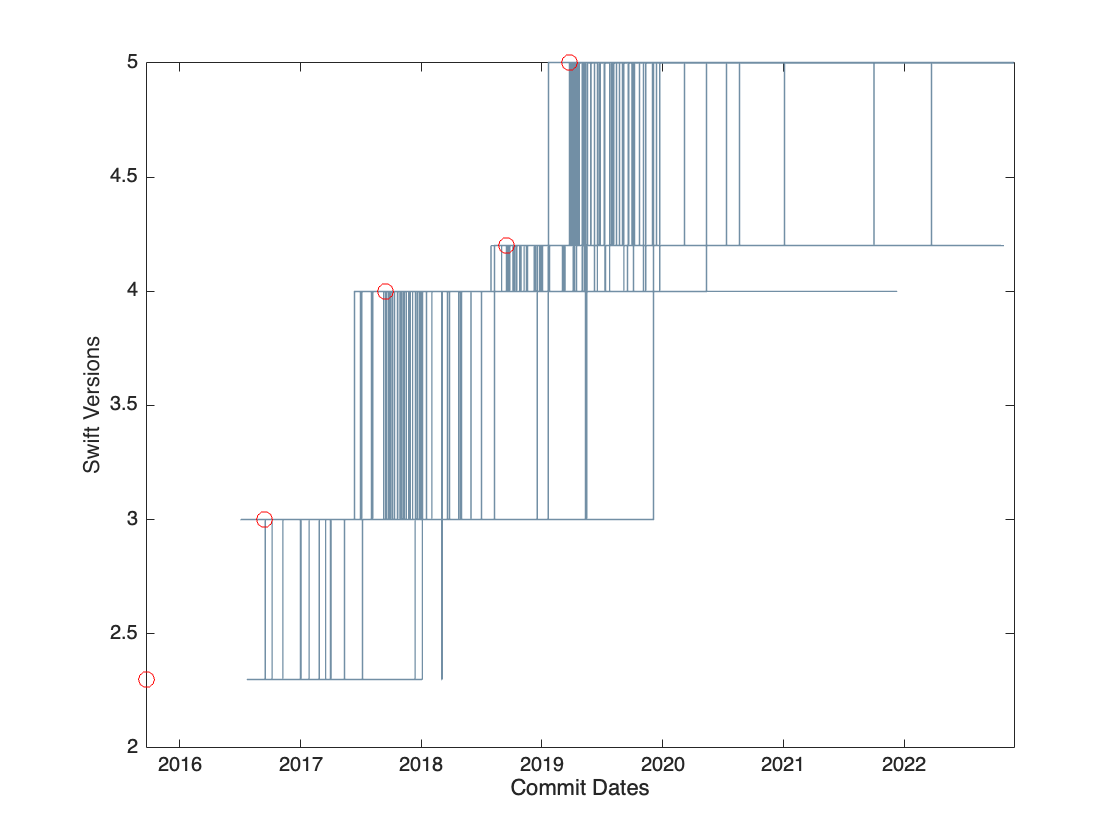

figure;
for i=1:length(data)
    dates = datetime;
    versions = [];
    t = 1;
    for j=1:length(data{i, 10})
        if isfield(data{i, 10}(j), "swiftVersion") && not(isempty(data{i, 10}(j).swiftVersion))
            dates(t) = data{i, 10}(j).dateTime;
            versions(t) = str2double(data{i, 10}(j).swiftVersion);

            version = str2double(data{i, 10}(j).swiftVersion);
            if version == 5.2
                versions(t) = 5;    
            elseif version == 4.1
                versions(t) = 4; 
            else
                versions(t) = version;
            end
            t = t+1;
        end
    end

    if not(isempty(versions))
        stairs(dates, versions, '-', 'Color', [114/255, 143/255, 165/255, 1], 'LineWidth', 0.7);
        hold on;
    end
end

plot([datetime("2015-09-21",'InputFormat','yyyy-MM-dd'), datetime("2016-09-13",'InputFormat','yyyy-MM-dd'), datetime("2017-09-14",'InputFormat','yyyy-MM-dd'), datetime("2018-09-17",'InputFormat','yyyy-MM-dd'), datetime("2019-03-25",'InputFormat','yyyy-MM-dd')],[2.3, 3, 4, 4.2, 5], 'o', 'MarkerSize', 8,'MarkerEdgeColor', 'red');
xlabel("Commit Dates")
ylabel("Swift Versions")
hold off;

The following code shows the distribution in the adoption of Swift versions in the latest commits of apps

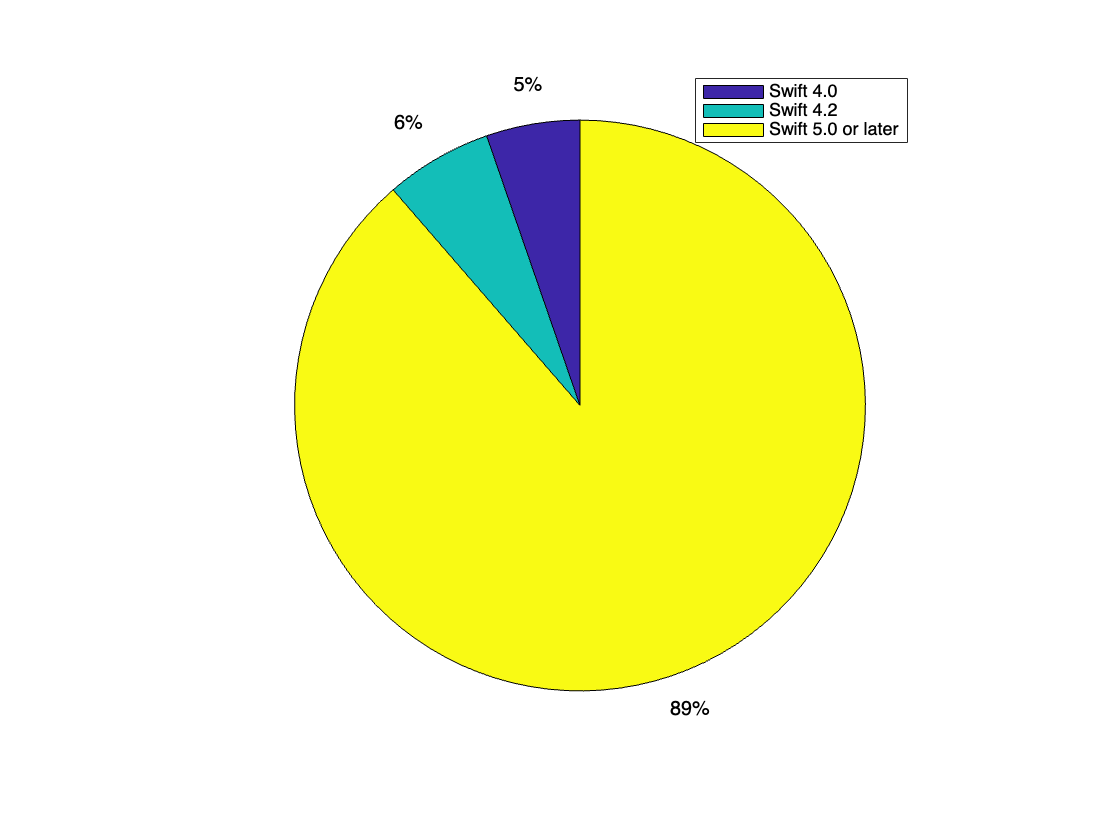

v5 = 0;
v42 = 0;
v4 = 0;
v3 = 0;
v2 = 0;

for i=1:length(data)
    if isfield(data{i,10}(end), "swiftVersion") && not(isempty(data{i, 10}(end).swiftVersion))
        version = str2double(data{i, 10}(end).swiftVersion);
        if version >= 5
            v5 = v5 + 1;
        elseif version >= 4.2
            v42 = v42 + 1;
        elseif version >= 4
            v4 = v4 + 1;
        elseif version >= 3
            v3 = v3 + 1;
        elseif version >= 2
            v2 = v2 + 1;
        end
    end
end

figure;
pie([v4, v42, v5])
legend("Swift 4.0", "Swift 4.2", "Swift 5.0 or later")